clearvars -except mapCD
loadif("D:\od\OneDrive\matlab\RawData\1T-TaS2(point defect)\mapCD.mat")

fldNm = 1×1 cell array
    {'mapCD'}



Your variables are:

fldNm  fn     mt     



ans = 'already'

## Quick Review of Coulomb Bloackade

### in case of I-V curve

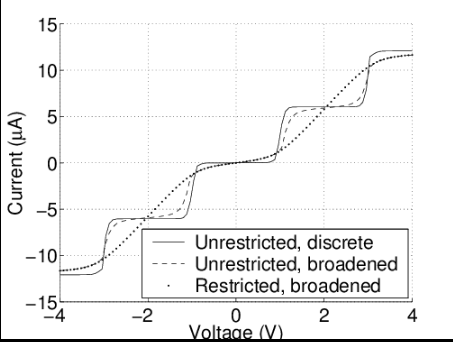

similar to step function.

### in case of G-V curve

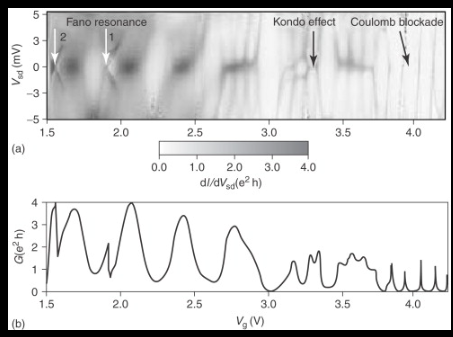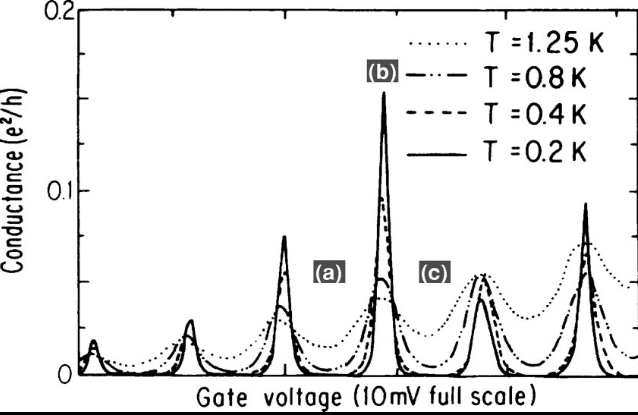

Ideally it is similar to Dirac comb.

## Our Dataset

### Survey global feature(Review previous data processing)

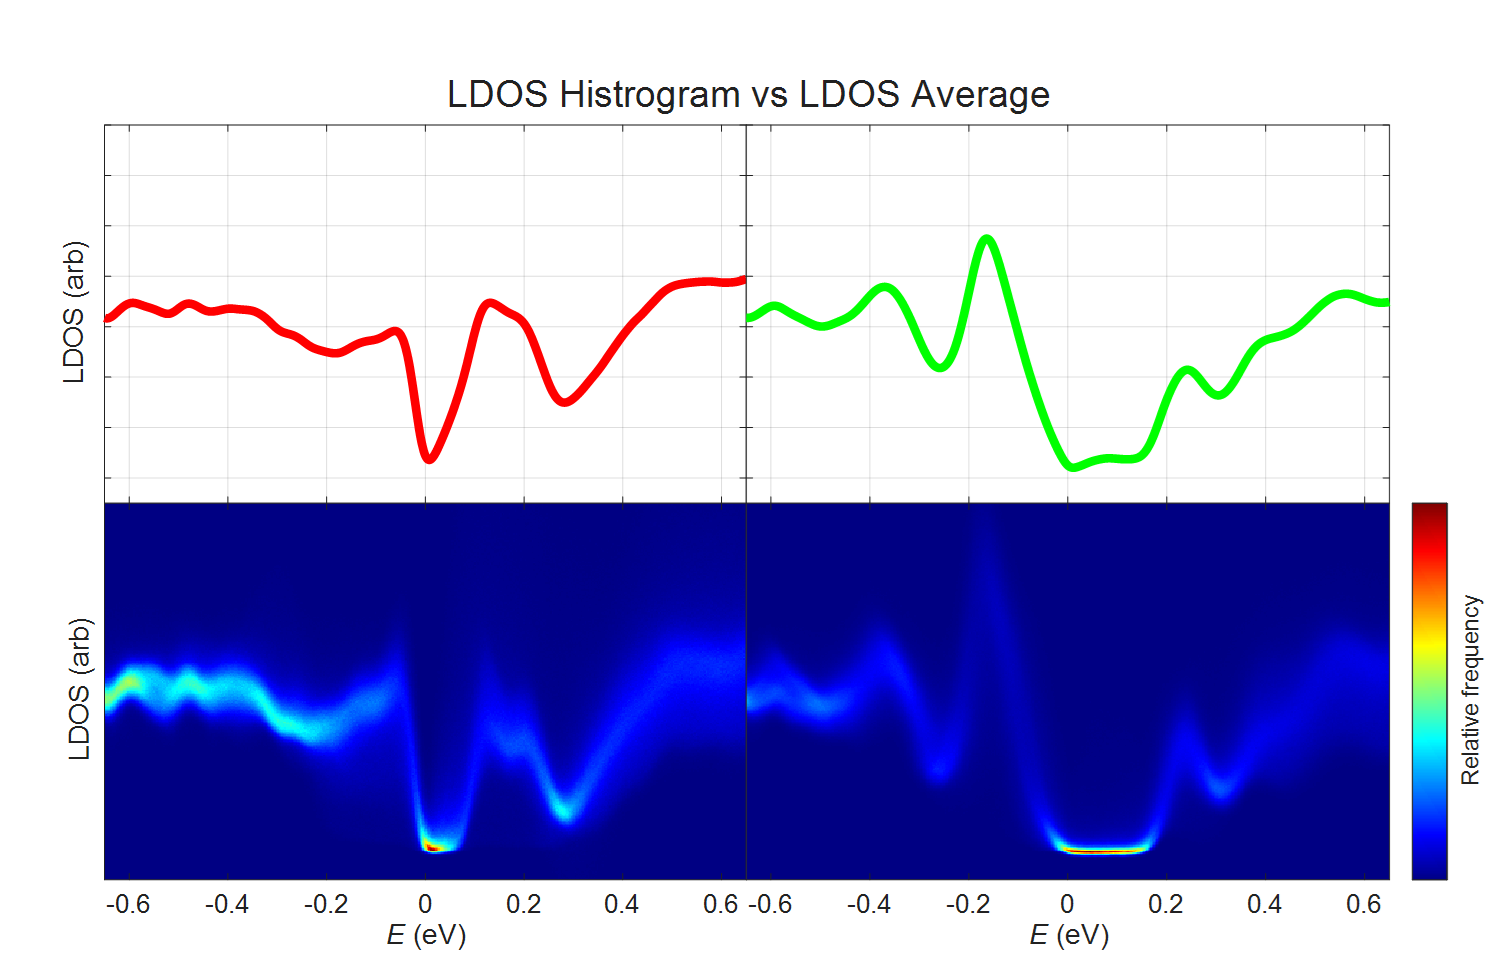

At glace, it is more visible in negative side.

In c-type(Mott case), step feature(~100mV) exist.

In a-type(trivial case), step featre(~200mV) exist but unclear.

### Survey local feature

To survey "quantum blockade" truly exist, we perform FFT.

I think it works well as I intended

#### Parameter

iph = 1

iph = 1

xypxl = [330 50]

xypxl =    330    50


vCrop = [-0.8 -0.2]

vCrop =    -0.8000   -0.2000


#### Figure setting

f = figure(1)

f =   Figure (refinepeaks) with properties:

      Number: 1
        Name: ''
       Color: [0.9608 0.9608 0.9608]
    Position: [1 41 1920 989]
       Units: 'pixels'

  Show all properties


f.Visible = 'on'

f =   Figure (refinepeaks) with properties:

      Number: 1
        Name: ''
       Color: [0.9608 0.9608 0.9608]
    Position: [1 41 1920 989]
       Units: 'pixels'

  Show all properties


#### Topo

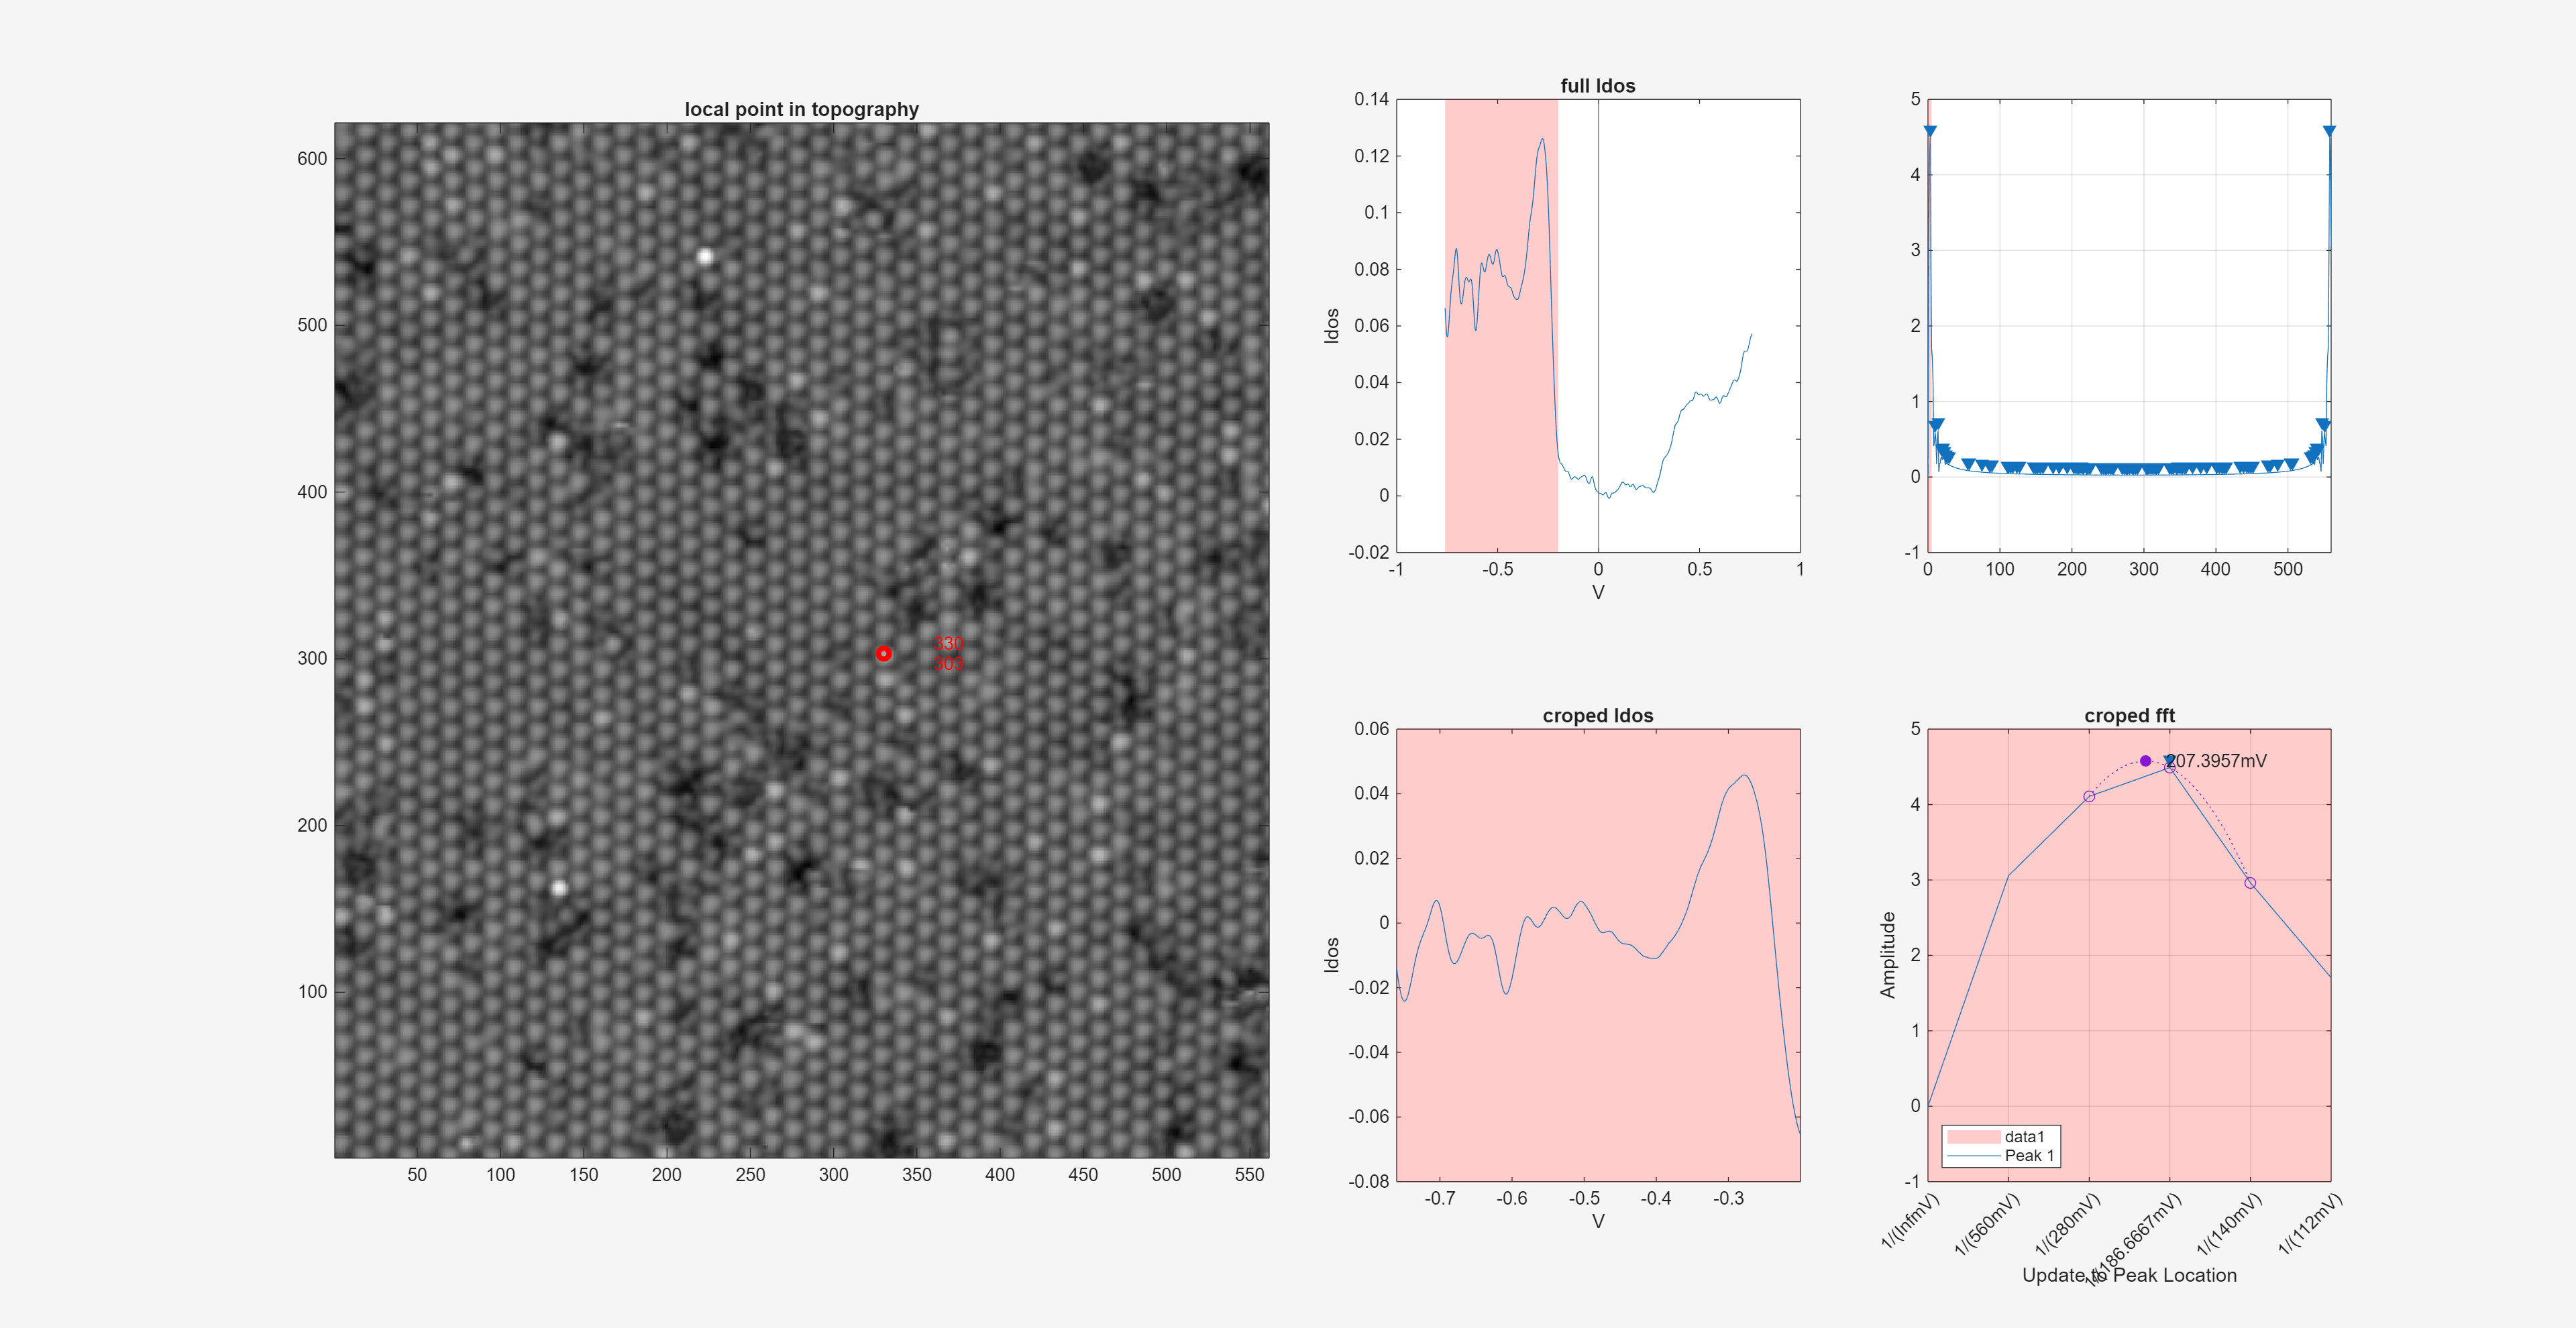

subplot(2,4,[1 2 5 6])

Z = mapCD.dt(iph).Z;

views(Z)


colormap gray
hold on
plot(xypxl(1),xypxl(2),'ro',LineWidth=3)
text(xypxl(1)+30,xypxl(2),string(xypxl),Color='r')
hold off
title('local point in topography')
fftCrop = [0 5];

#### full ldos

subplot(2,4,3)
v = mapCD.V;
ldos = squeeze(mapCD.dt(iph).G(xypxl(1),xypxl(2),:));
plot(v,ldos);
xline(0)
xlabel('V')
ylabel('ldos')
title('full ldos')

[~,ind] = min(abs(v'-vCrop))

ind =      1   561


% xline(v(ind),'--','crop')
vind = v(ind);
highlightXRange(vind)

ans =   Patch with properties:

    FaceColor: [1 0 0]
    FaceAlpha: 0.2000
    EdgeColor: 'none'
    LineStyle: '-'
        Faces: [1 2 3 4]
     Vertices: [4×2 double]

  Show all properties


#### croped ldos

subplot(2,4,7)
iCr = ind(1):ind(2);
vCr = v(iCr);
ldosCr = ldos(iCr);
ldosCr = ldosCr - mean(ldosCr)

ldosCr =     0.0111
    0.0110
    0.0109
    0.0108
    0.0107
    0.0107
    0.0106
    0.0106
    0.0106
    0.0106
    0.0107
    0.0108
    0.0109
    0.0111
    0.0114


% ldosCr = sin(iCr)
plot(vCr,ldosCr)
xlabel('V')
ylabel('ldos')
title('croped ldos')
highlightXRange(vind)

ans =   Patch with properties:

    FaceColor: [1 0 0]
    FaceAlpha: 0.2000
    EdgeColor: 'none'
    LineStyle: '-'
        Faces: [1 2 3 4]
     Vertices: [4×2 double]

  Show all properties


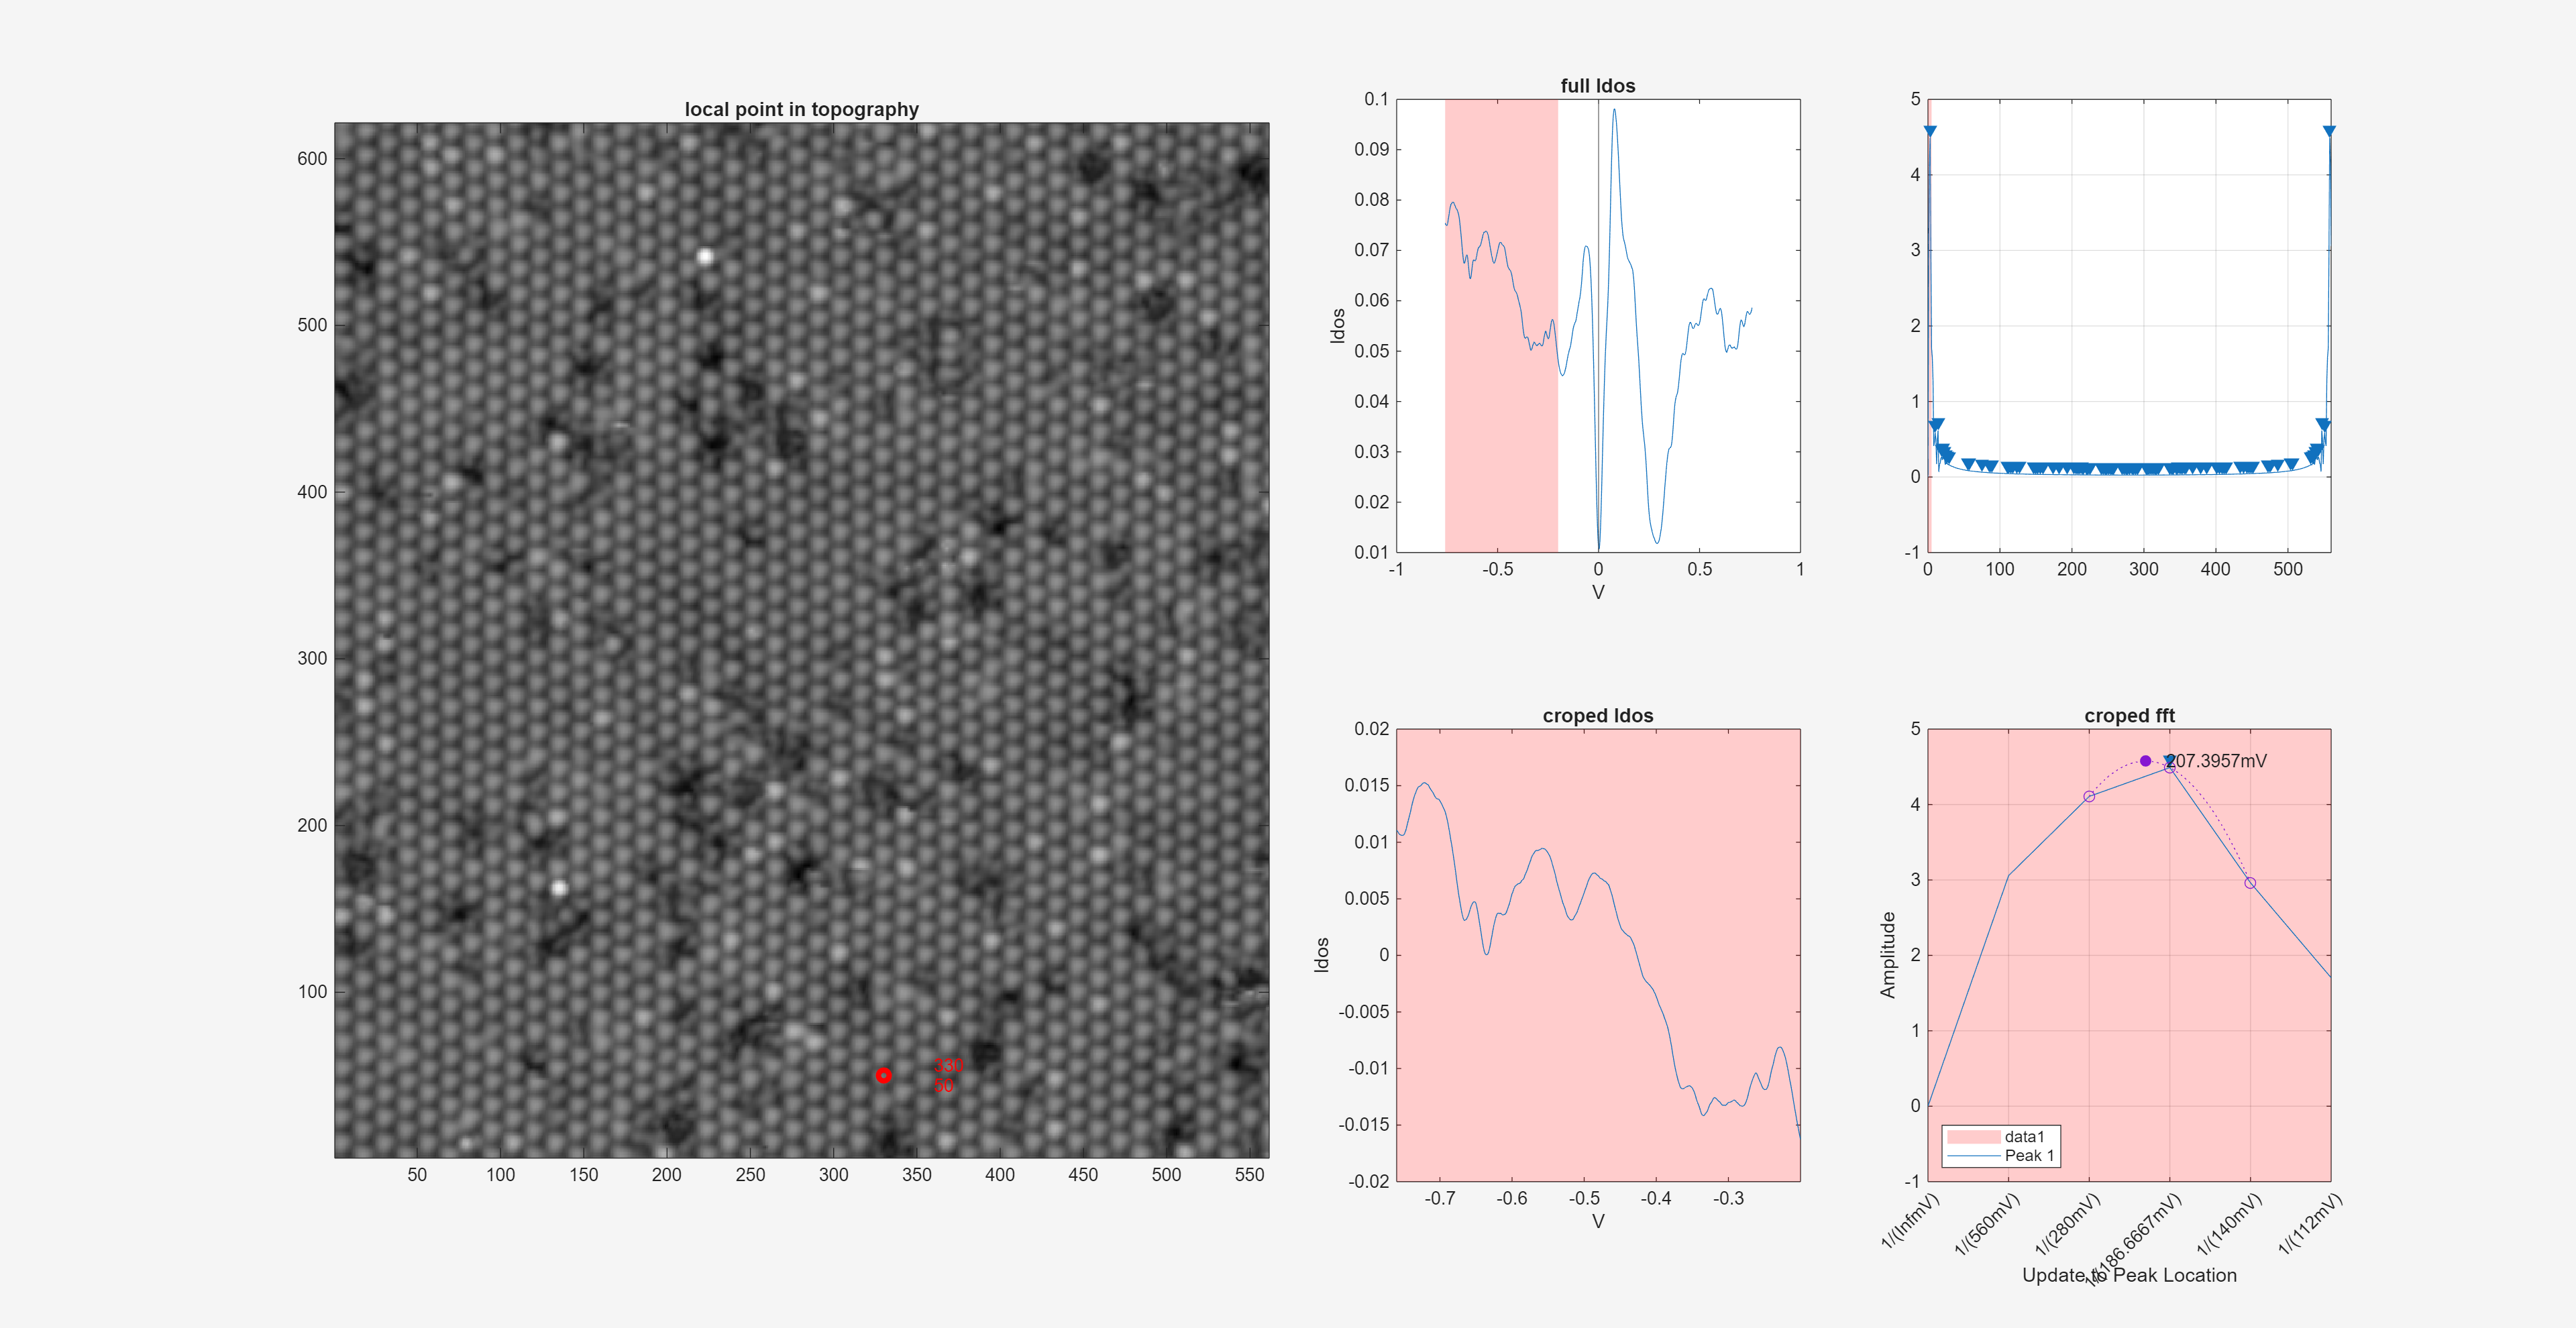

xlim(vind)

#### full fft

subplot(2,4,4)
fs = (1:length(ldosCr))-1

fs =      0     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    35    36    37    38    39    40    41    42    43    44    45    46    47    48    49


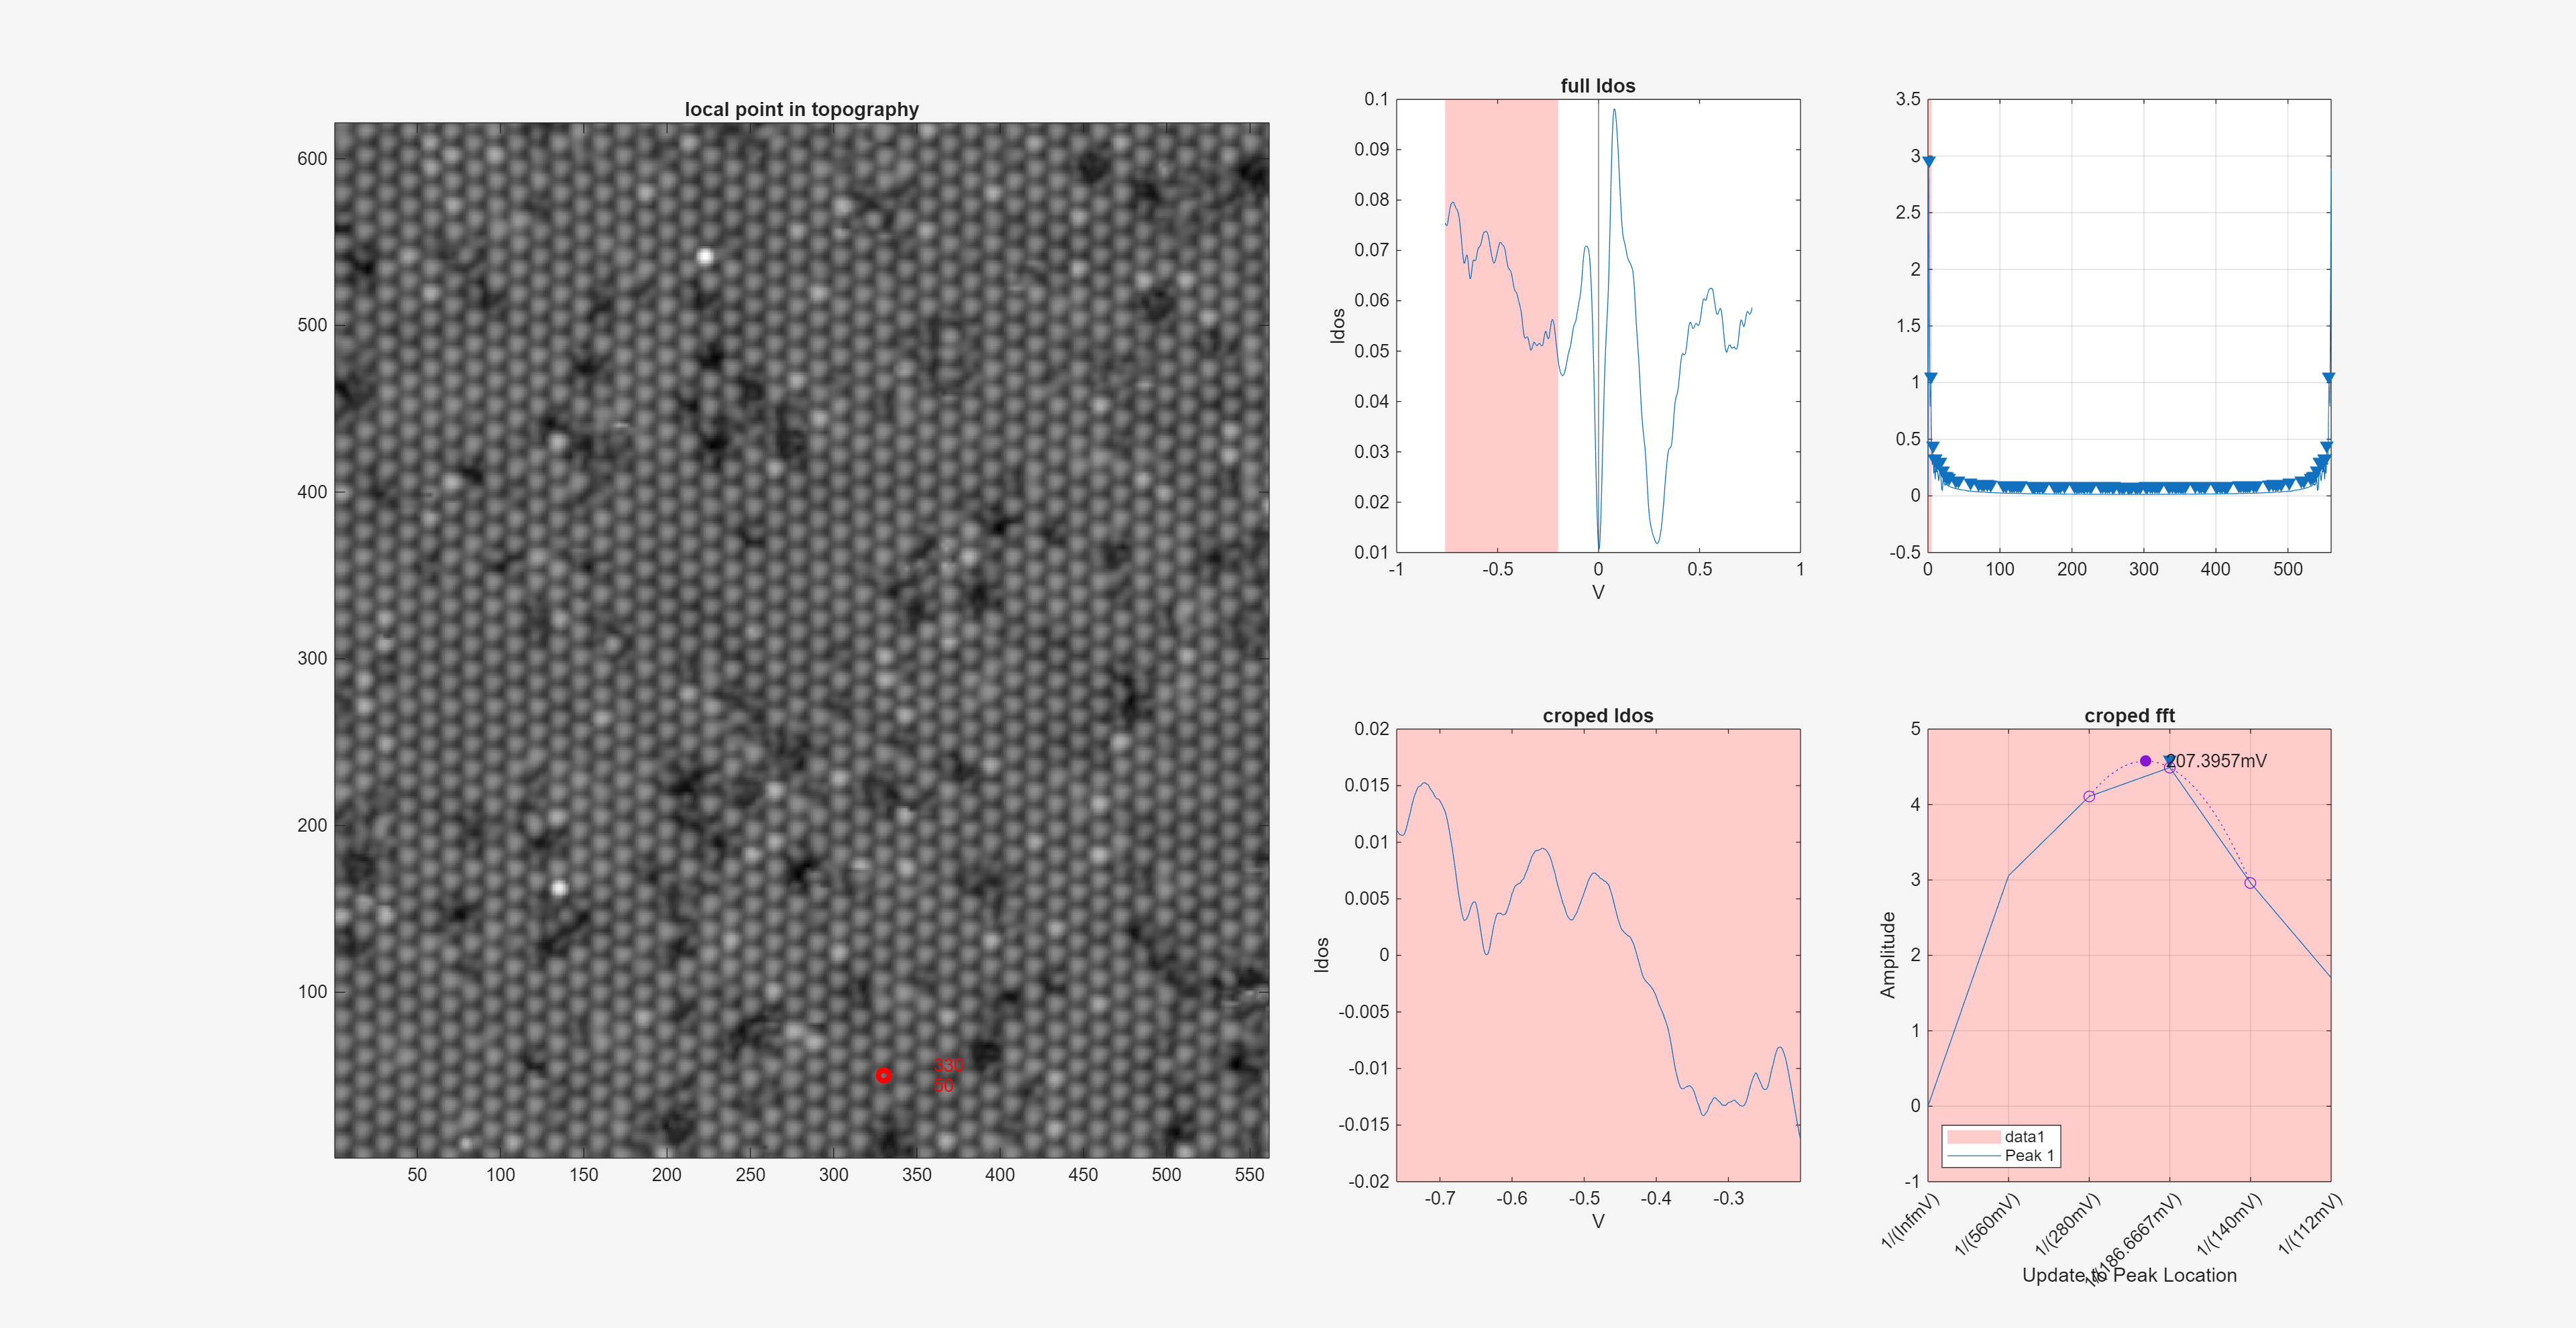

ans =   Patch with properties:

    FaceColor: [1 0 0]
    FaceAlpha: 0.2000
    EdgeColor: 'none'
    LineStyle: '-'
        Faces: [1 2 3 4]
     Vertices: [4×2 double]

  Show all properties


abfft = abs(fft(ldosCr));
xlabel("f(1/T unit)")
title("full fft")

findpeaks(abfft,fs)
highlightXRange(fftCrop)

#### croped fft

subplot(2,4,8)

plot(fs,abfft,'r')

ax = gca

ax =   Axes with properties:

             XLim: [0 600]
             YLim: [0 3]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.7484 0.1100 0.1566 0.3412]
            Units: 'normalized'

  Show all properties


xlim(fftCrop)

findpeaks(abfft,fs)
[pks,idx] = findpeaks(abfft,fs)

pks =     2.8872
    0.9837
    0.3702
    0.2618
    0.2621
    0.2266
    0.2293
    0.1502
    0.1085
    0.1004
    0.0886
    0.0648
    0.0627
    0.0439
    0.0362


idx =      1     4     7     9    11    13    17    21    25    27    29    39    42    59    70    75    78    82    87   105   109   114   117   120   123   126   129   145   147   149   152   155   159   161   176   178   181   184   190   204   206   208   210   213   216   218   221   225   227   240


hold on
idx_pkcand =  idx(1)

idx_pkcand = 1

refinepeaks(abfft,idx_pkcand + 1)
% ax.Children.DisplayName
% findobj(ax, 'DisplayName', '(RefinedCurve)')
ax.Children

ans =   6×1 graphics array:

  Line       (RefinedCurve)
  Scatter    (InitialPeak)
  Scatter    (EdgeSample)
  Scatter    (RefinedPeak)
  Line       (Peak)
  Line       (Signal)


hold off
xlim(fftCrop)
highlightXRange(fftCrop)

ans =   Patch (data1) with properties:

    FaceColor: [1 0 0]
    FaceAlpha: 0.2000
    EdgeColor: 'none'
    LineStyle: '-'
        Faces: [1 2 3 4]
     Vertices: [4×2 double]

  Show all properties


title("croped fft")
rfobj = findobj(ax,{'Tag'},{'RefinedCurve';'InitialPeak';'EdgeSample';'RefinedPeak'})

rfobj =   4×1 graphics array:

  Line       (RefinedCurve)
  Scatter    (InitialPeak)
  Scatter    (EdgeSample)
  Scatter    (RefinedPeak)


for idx = 1:length(rfobj)
rfobj(idx).XData = rfobj(idx).XData + idx_pkcand
end

rfobj =   4×1 graphics array:

  Line       (RefinedCurve)
  Scatter    (InitialPeak)
  Scatter    (EdgeSample)
  Scatter    (RefinedPeak)


rfobj =   4×1 graphics array:

  Line       (RefinedCurve)
  Scatter    (InitialPeak)
  Scatter    (EdgeSample)
  Scatter    (RefinedPeak)


rfobj =   4×1 graphics array:

  Line       (RefinedCurve)
  Scatter    (InitialPeak)
  Scatter    (EdgeSample)
  Scatter    (RefinedPeak)


rfobj =   4×1 graphics array:

  Line       (RefinedCurve)
  Scatter    (InitialPeak)
  Scatter    (EdgeSample)
  Scatter    (RefinedPeak)


rfobj(1).LineStyle = ':'

rfobj =   4×1 graphics array:

  Line       (RefinedCurve)
  Scatter    (InitialPeak)
  Scatter    (EdgeSample)
  Scatter    (RefinedPeak)


T = abs(vind(1)-vind(2))*1000

T = 560.0000


str = "    "+string(T/rfobj(4).XData) +"mV"

str = "    472.3682mV"

hold on
text(rfobj(4).XData,rfobj(4).YData,str)
hold off
(T)./(ax.XTick)

ans =        Inf  560.0000  280.0000  186.6667  140.0000  112.0000


string(T./ax.XTick)

ans = 1×6 string array
    "Inf"    "560"    "280"    "186.6667"    "140"    "112"


ax.XTickLabel =  ("1/("+string(T./ax.XTick) +"mV)")'

ax =   Axes (croped fft) with properties:

             XLim: [0 5]
             YLim: [-0.5000 3.5000]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.7484 0.1100 0.1566 0.3412]
            Units: 'normalized'

  Show all properties


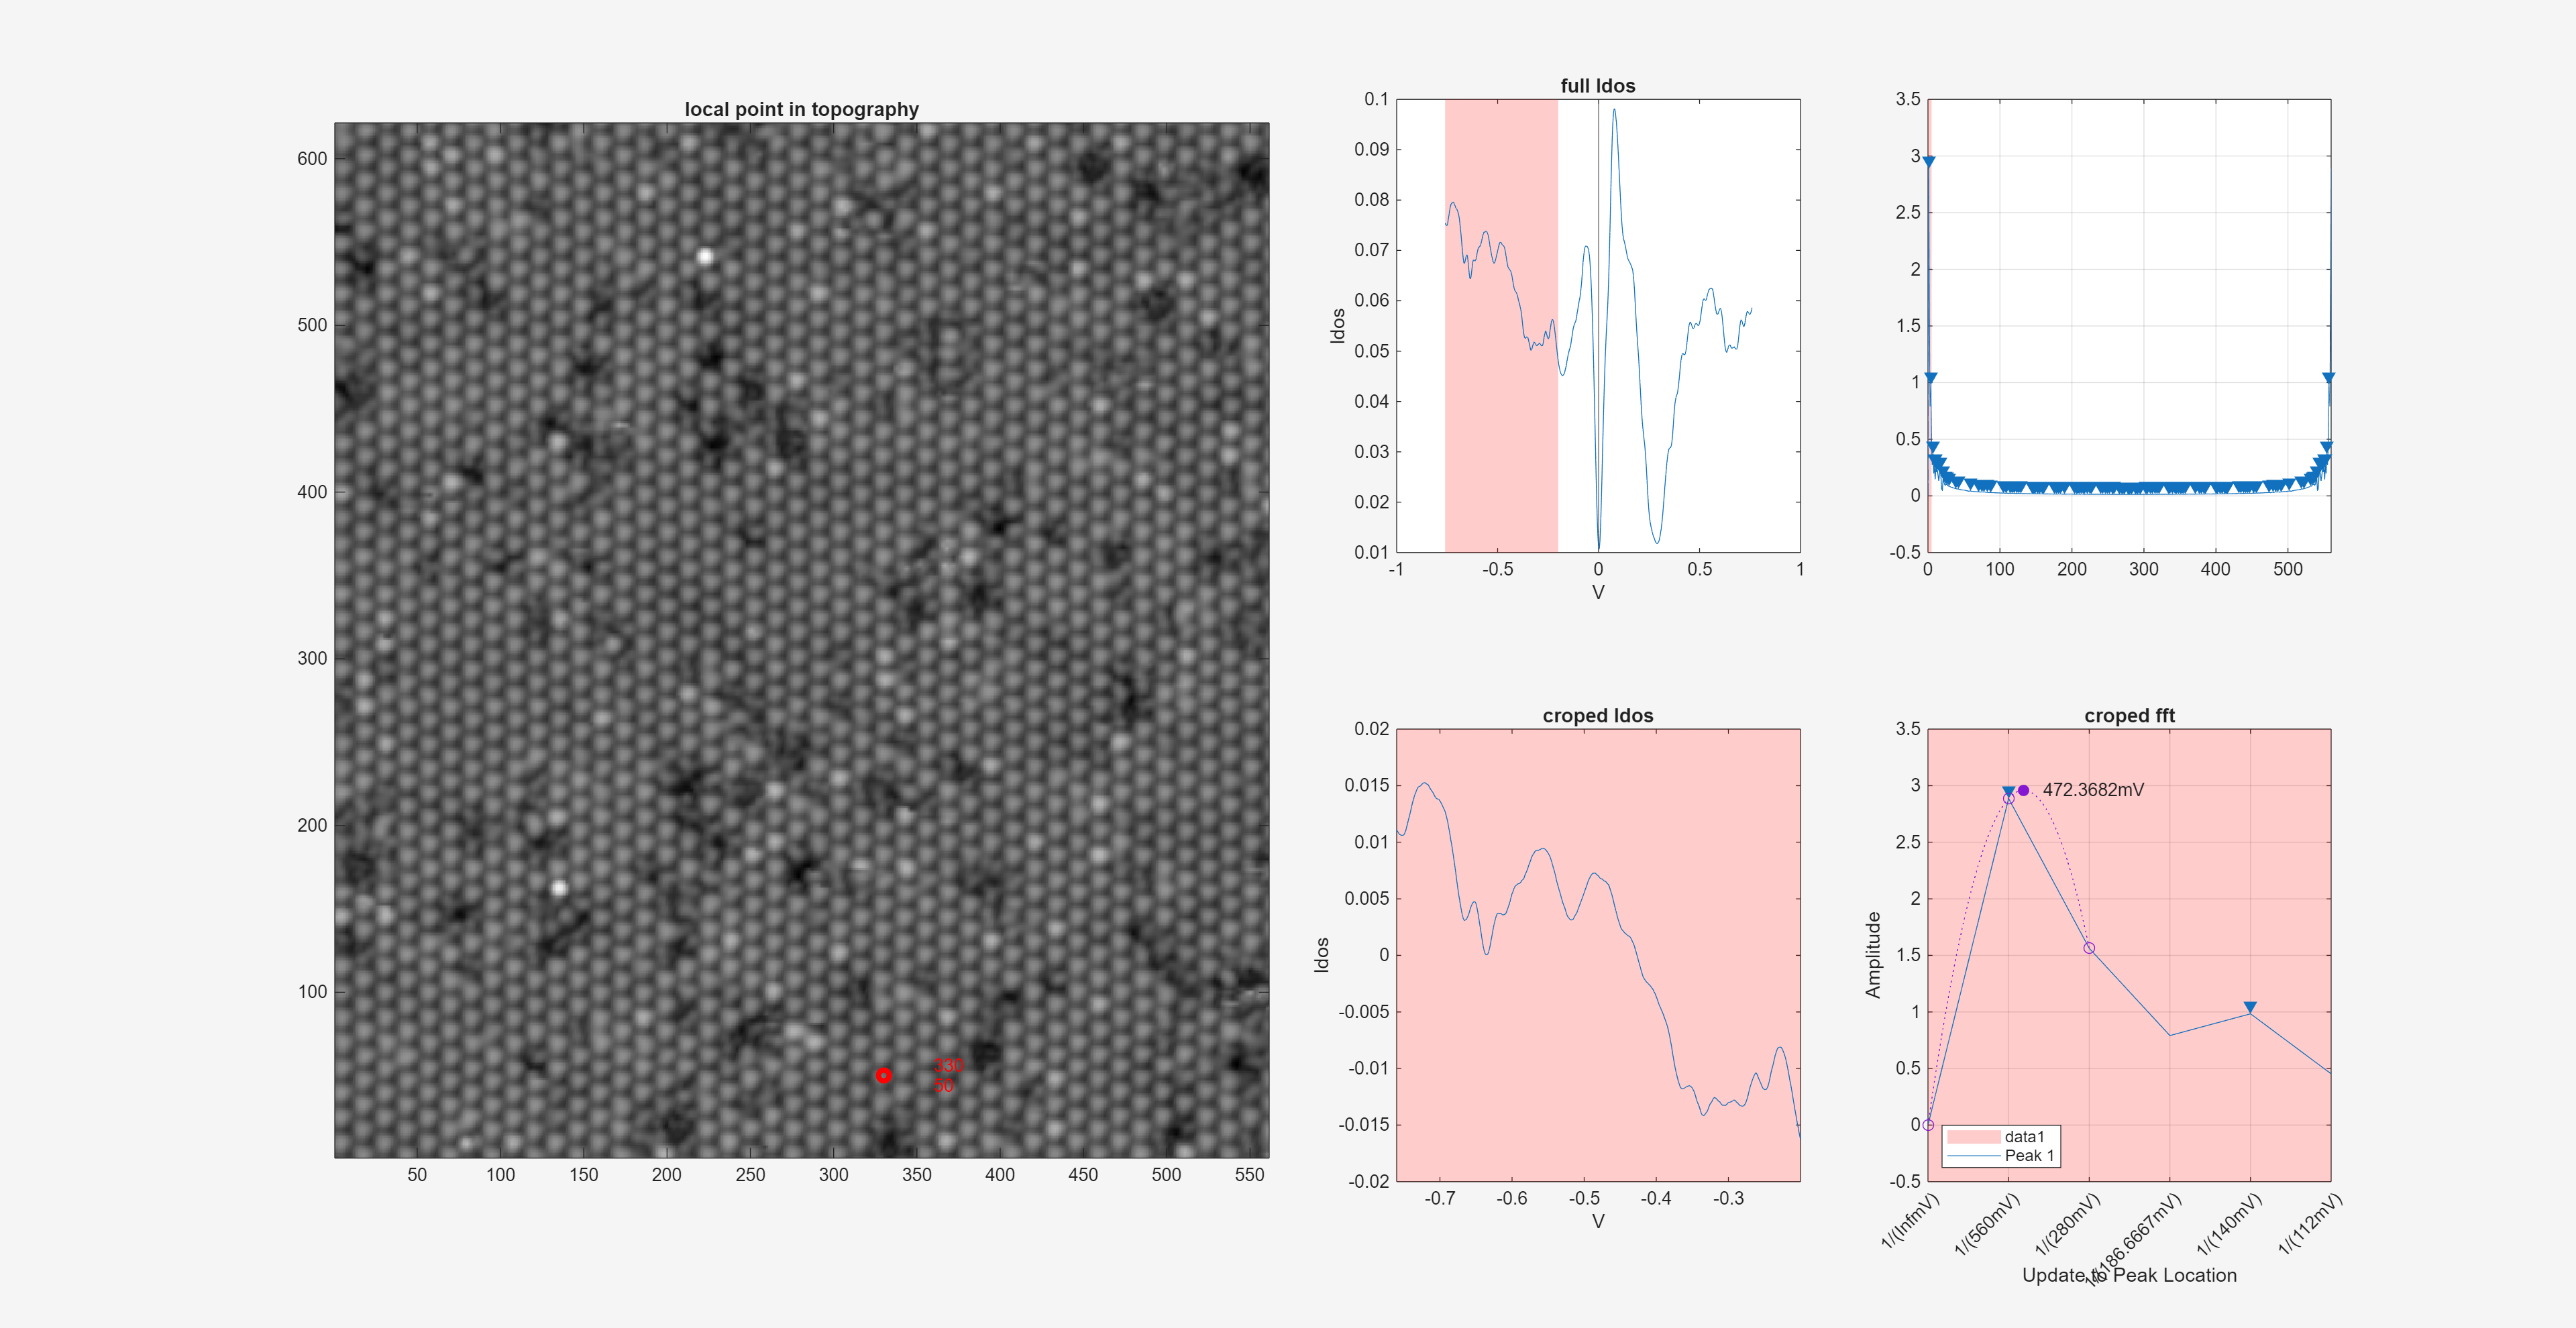

ax =   Axes (croped fft) with properties:

             XLim: [0 5]
             YLim: [-0.5000 3.5000]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.7484 0.1100 0.1566 0.3412]
            Units: 'normalized'

  Show all properties


ax.XTickLabelRotation = 45

function h = highlightXRange(x_minmax, color, alpha)
% HIGHLIGHTXRANGE Highlights a specific x-range on the current axes
%
% Inputs:
%   x_minmax - Two-element vector [x_min, x_max] specifying the region to highlight
%   color    - Color of the highlight (default: 'red')
%   alpha    - Opacity level from 0 to 1 (default: 0.2)
%
% Output:
%   h        - Handle to the created patch object
%
% Example:
%   plot(1:10, sin(1:10));
%   highlightXRange([3, 6], 'blue', 0.3);

% Validate input
if ~isvector(x_minmax) || length(x_minmax) ~= 2
    error('x_minmax must be a two-element vector [x_min, x_max]');
end

x_min = min(x_minmax);
x_max = max(x_minmax);

% Handle default parameters
if nargin < 2 || isempty(color)
    color = 'red';
end

if nargin < 3 || isempty(alpha)
    alpha = 0.2;
end

% Get current axis limits
ax = gca;
y_limits = ylim(ax);

% Create patch coordinates
x_patch = [x_min, x_max, x_max, x_min];
y_patch = [y_limits(1), y_limits(1), y_limits(2), y_limits(2)];

% Create the patch
h = patch(x_patch, y_patch, color, 'FaceAlpha', alpha, 'EdgeColor', 'none');

% Make sure the patch stays in the background
uistack(h, 'bottom');

% Ensure the y-limits don't change due to the patch
ylim(y_limits);

end